clc
clear
close all

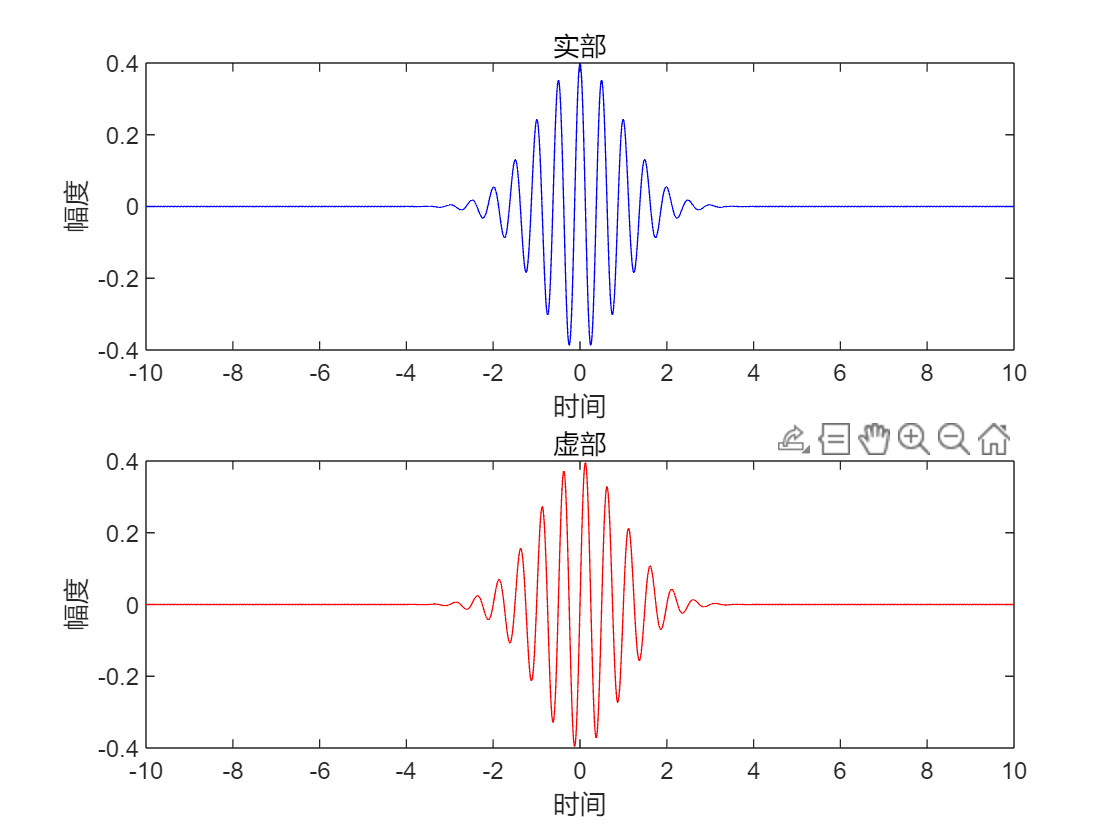

fc = 2; 
fb = 2; 
t = -10:0.01:10;
% 小波基函数
psi = (1/sqrt(pi*fb))*exp(1i*2*pi*fc*t).*exp(-t.^2/fb);
figure;
subplot(211)
plot(t, real(psi), 'b');
xlabel('时间');
ylabel('幅度');
title('实部');
subplot(212)
plot(t, imag(psi), 'r');
xlabel('时间');
ylabel('幅度');
title('虚部');

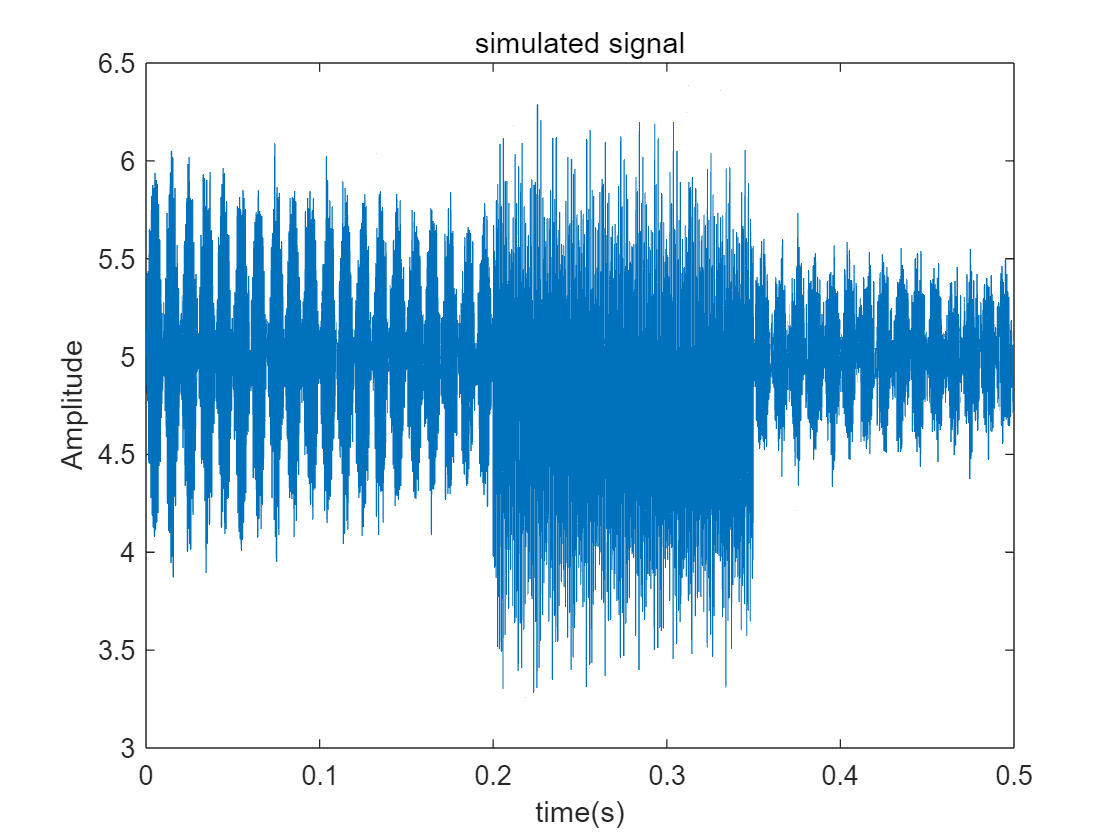

fs = 1e4;            % 采样频率
ts = 0.5;            % 信号持续时间（秒）
t=1/fs:1/fs:ts;
signal = 5+sin(2*pi*50*t).*cos(2 *pi*1530*t).*exp(-t./0.5)+ sawtooth(2*pi*2500*t).*((t >= 0.2) & (t < 0.35));
% 信噪比和信号指定功率
snr=20;
px_dBW=0;
ft=awgn(signal,snr,px_dBW);
figure
plot(t,ft)
xlabel('time(s)')
ylabel('Amplitude')
title("simulated signal")

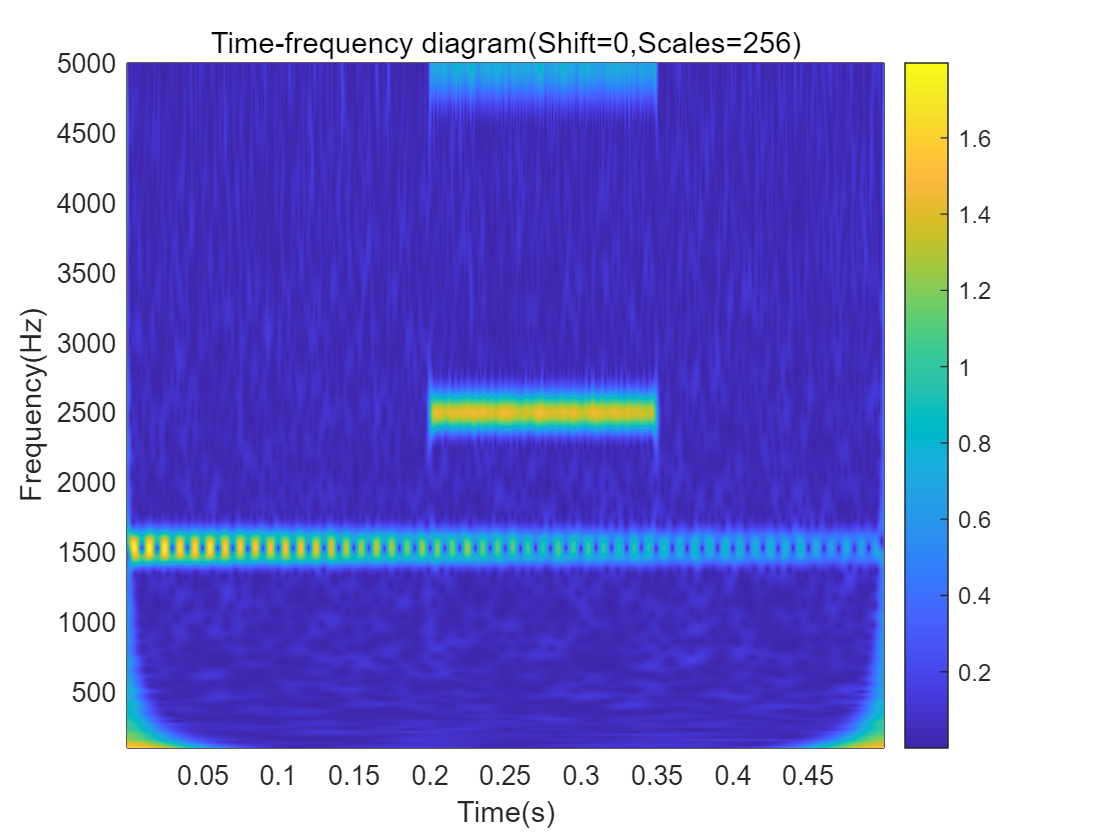

fc = 4; 
fb = 2; 
dt = 0;                                % 时移
totalscale = 256;                      % 所取尺度的数目                                         
Freq = linspace(0.01,0.5,totalscale);  % 将频率轴在分析范围内等间隔划分
Scales = fc./ Freq;                    % 计算相应的尺度参数
wcoefs = mycwt(ft,Scales,fc,fb,dt);  
RealFreq = Freq*fs;  
figure
pcolor(t,RealFreq,abs(wcoefs));
shading interp;
axis([min(t) max(t) min(RealFreq) max(RealFreq)]);
colorbar;
xlabel('Time(s)');
ylabel('Frequency(Hz)');
title('Time-frequency diagram(Shift=0,Scales=256)')

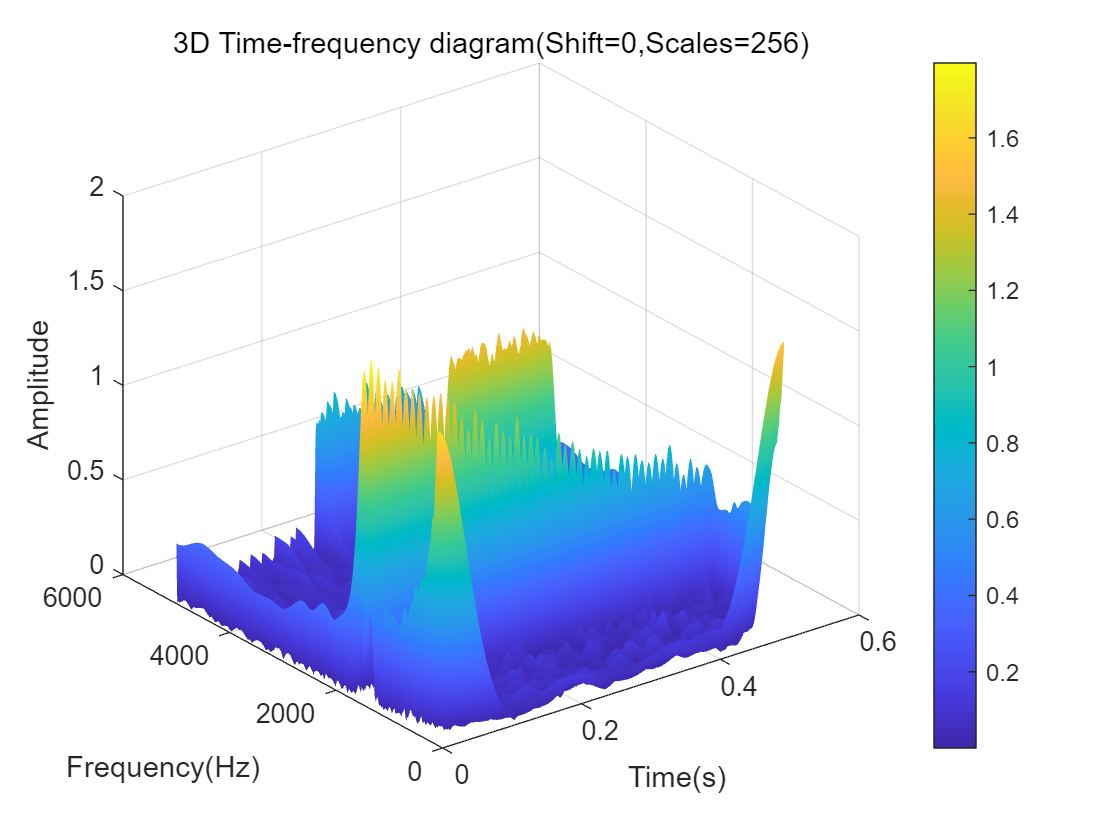

figure
surf(t,RealFreq,abs(wcoefs))
xlabel('Time(s)');
ylabel('Frequency(Hz)');
zlabel('Amplitude')
title('3D Time-frequency diagram(Shift=0,Scales=256)')
colorbar;
shading interp;

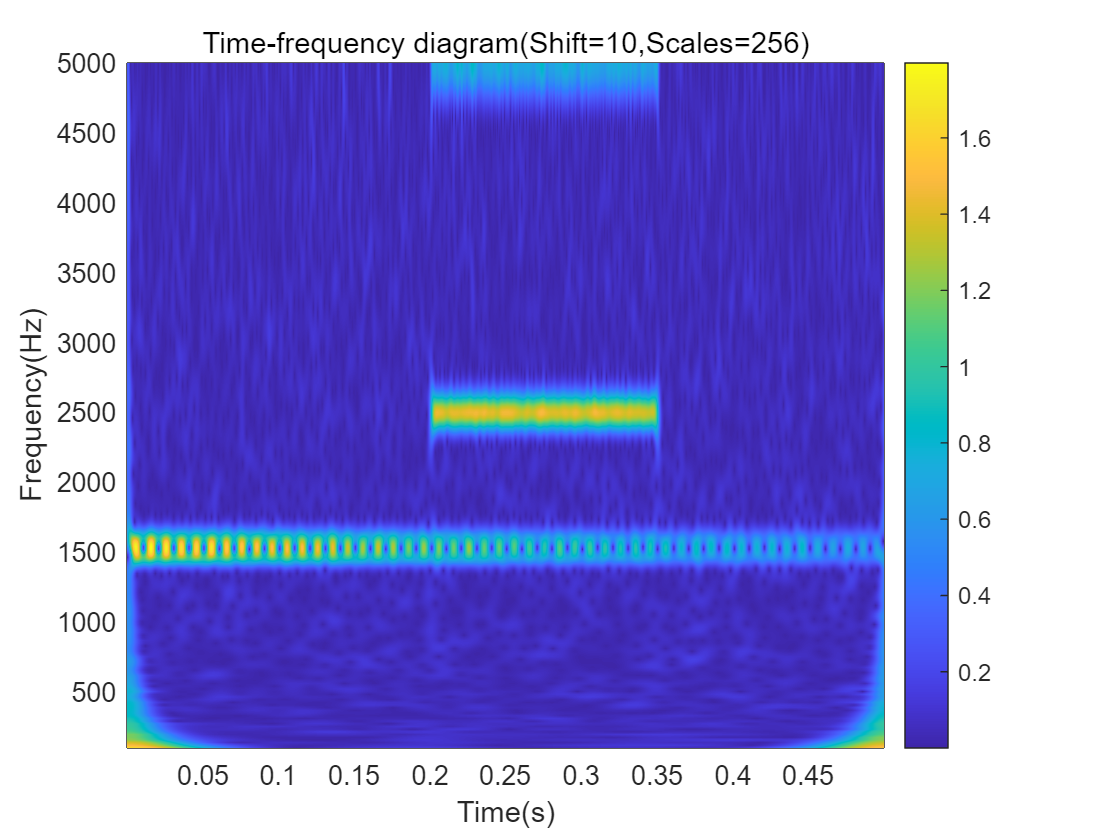

dt = 10;
totalscale = 256;                      % 所取尺度的数目                                         
Freq = linspace(0.01,0.5,totalscale);  % 将频率轴在分析范围内等间隔划分
Scales = fc./ Freq;                    % 计算相应的尺度参数
wcoefs = mycwt(ft,Scales,fc,fb,dt);  
RealFreq = Freq*fs;  
figure
pcolor(t,RealFreq,abs(wcoefs));
shading interp;
axis([min(t) max(t) min(RealFreq) max(RealFreq)]);
colorbar;
xlabel('Time(s)');
ylabel('Frequency(Hz)');
title('Time-frequency diagram(Shift=10,Scales=256)')

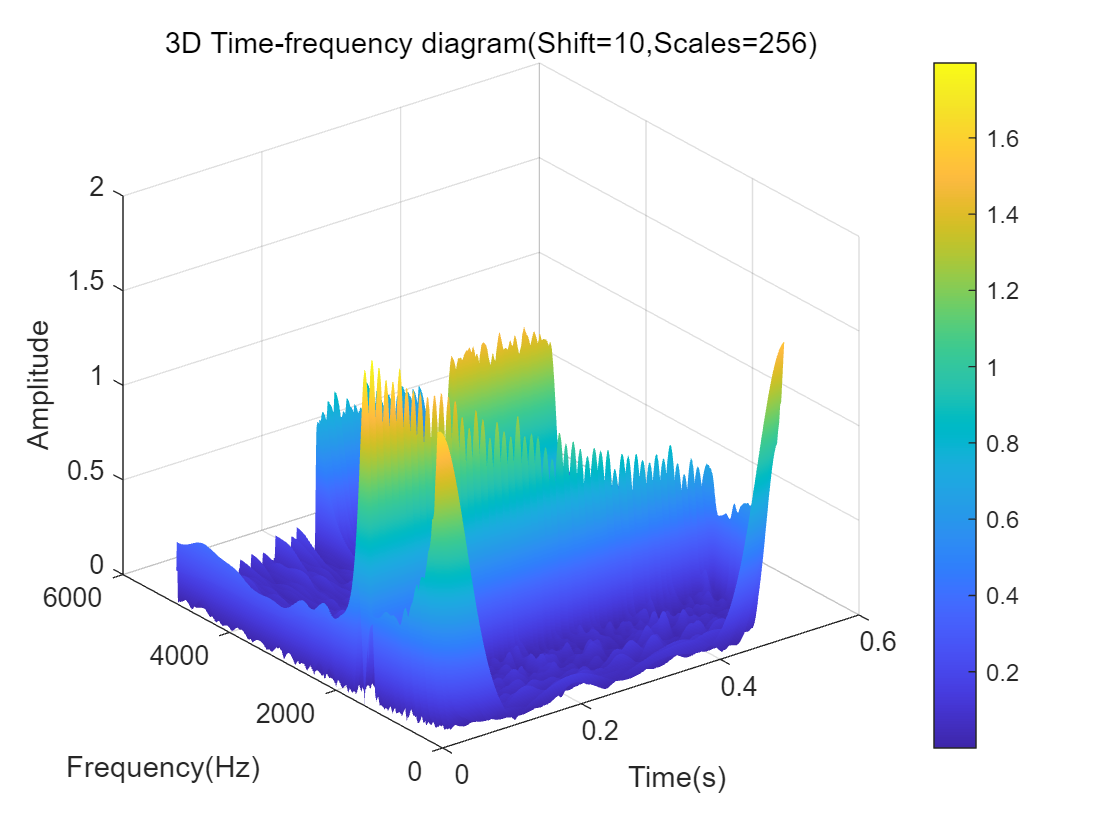

figure
surf(t,RealFreq,abs(wcoefs))
xlabel('Time(s)');
ylabel('Frequency(Hz)');
zlabel('Amplitude');
title('3D Time-frequency diagram(Shift=10,Scales=256)')
colorbar;
shading interp;

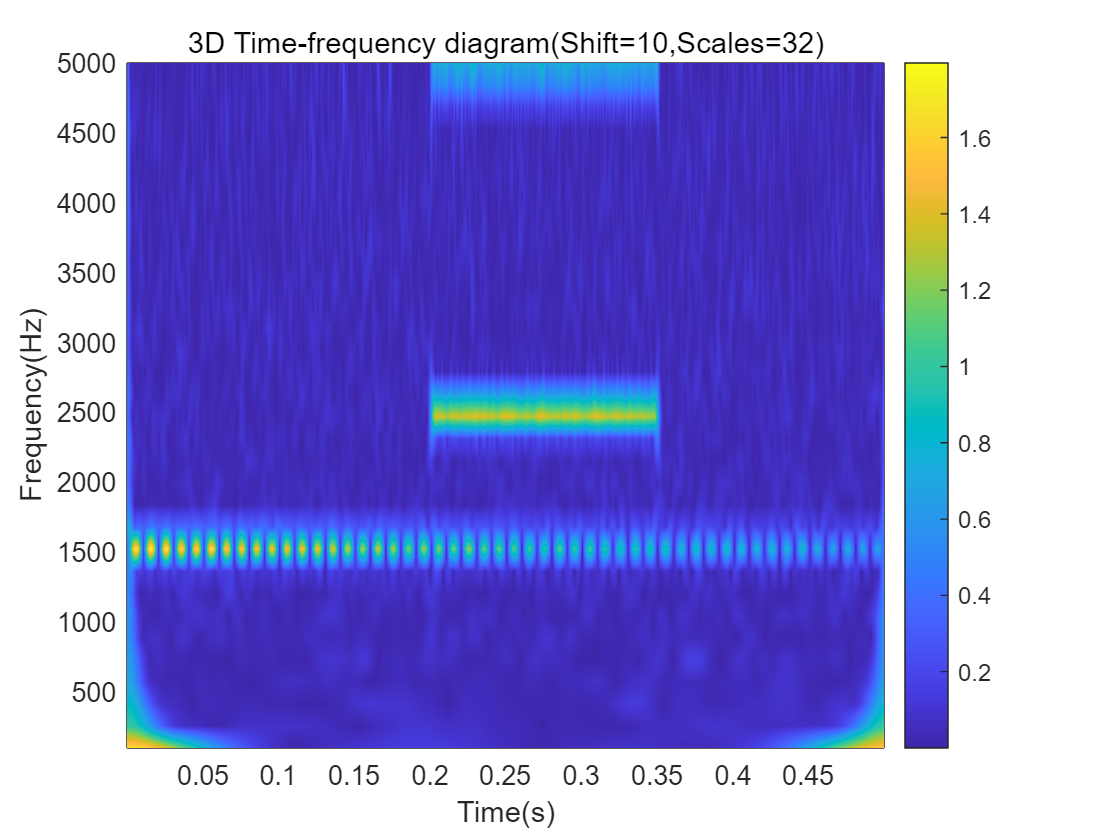

dt = 10;
totalscale = 32;                      % 所取尺度的数目                                         
Freq = linspace(0.01,0.5,totalscale);  % 将频率轴在分析范围内等间隔划分
Scales = fc./ Freq;                    % 计算相应的尺度参数
wcoefs = mycwt(ft,Scales,fc,fb,dt);  
RealFreq = Freq*fs;  
figure
pcolor(t,RealFreq,abs(wcoefs));
shading interp;
axis([min(t) max(t) min(RealFreq) max(RealFreq)]);
colorbar;
xlabel('Time(s)');
ylabel('Frequency(Hz)');
title('3D Time-frequency diagram(Shift=10,Scales=32)')

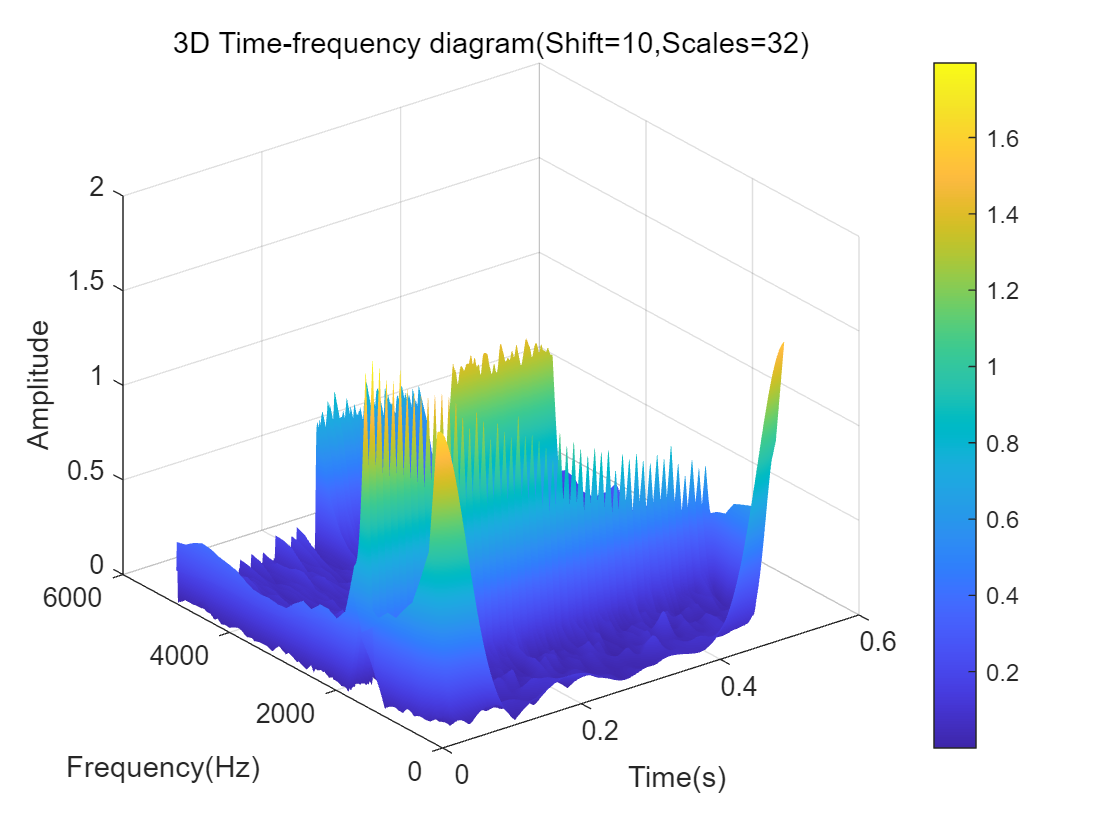

figure
surf(t,RealFreq,abs(wcoefs))
xlabel('Time(s)');
ylabel('Frequency(Hz)');
zlabel('Amplitude');
title('3D Time-frequency diagram(Shift=10,Scales=32)')
colorbar;
shading interp;

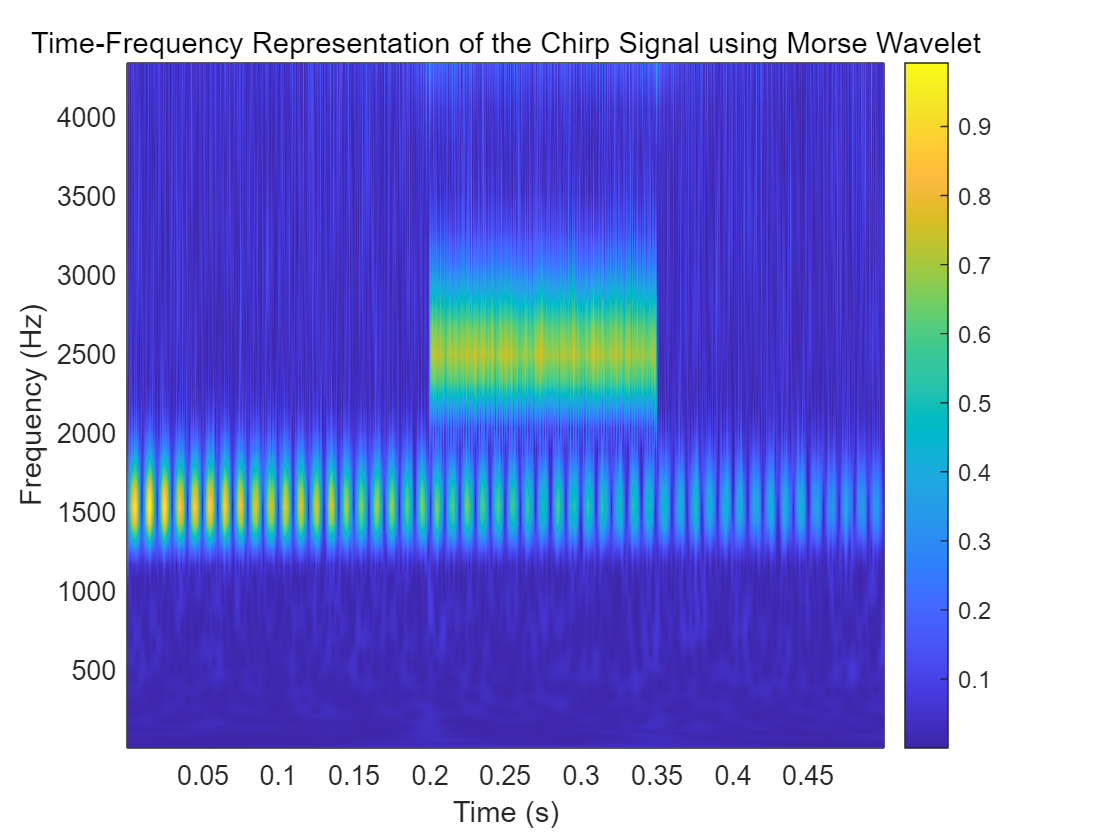


[wcoef_morse, freq_morse] = cwt(ft, fs, 'Morse');
figure
pcolor(t, freq_morse, abs(wcoef_morse));
shading interp;
title('Time-Frequency Representation of the Chirp Signal using Morse Wavelet');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
colorbar;

function wcoefs = mycwt(signal,scales,fc,fb,dt)
wavsupport=8; 
nLevel=length(scales); 
siglen = length(signal);  % 信号的长度
wcoefs = zeros(nLevel, siglen);         
    for m = 1:nLevel      % 计算各尺度上的小波系数
        a = scales(m);    % 提取尺度参数                              
        t = -round(a*wavsupport):1:round(a*wavsupport);  
        %小波母函数
        phi = (pi*fb)^(-1/2)*exp(1i*2*pi*fc*(t-dt)/a).*exp(-(t-dt).^2/(fb*a^2)); 
        temp = conv(signal,phi) /sqrt(a); 
        %由于卷积计算所得结果的长度可能远远大于原信号，提取按原信号的长度提取中间部分的系数
        d=(length(temp)-siglen)/2;
        %区间的起点
        first = 1+floor(d);    
        wcoefs(m,:)=temp(first:first+siglen-1);   
    end
end